## Exercise 4

clc     %Clearing all graphs and figures
close all
clear
syms z w x(t) x0        %Declaring syms

myode = diff(x,2) + 2*z*w*diff(x) + w^2*x == 0      %a defining Differential Equation

$$myode(t) = \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+2\,z\,w\,\frac{\partial }{\partial t}x\left(t\right)+x\left(t\right)\,w^{2}=0$$

dx = diff(x);
mycond = [x(0)==x0 dx(0)==0]        %Inputting initial values

$$mycond = \left(\begin{array}{cc} x\left(0\right)=x_{0} & \left({\left(\frac{\partial }{\partial t}x\left(t\right)\right)|}_{t=0}\right)=0 \end{array}\right)$$


x = dsolve(myode,mycond)        %b Solving ode for initial conditions

$$x = \begin{array}{l} \frac{x_{0}\,{\mathrm{e}}^{t\,\left(w\,\sigma_{1}-w\,z\right)}\,\left(z+\sigma_{1}\right)}{2\,\sigma_{1}}-\frac{x_{0}\,{\mathrm{e}}^{-t\,\left(w\,\sigma_{1}+w\,z\right)}\,\left(z-\sigma_{1}\right)}{2\,\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=\sqrt{\left(z-1\right)\,\left(z+1\right)} \end{array}$$


x1 = subs(x,[x0 z w], [1 .1 10])        %c graphing for different z values

$$x1 = -\frac{5\,\sqrt{99}\,{\mathrm{e}}^{t\,\left(-1+\sqrt{99}\,\mathrm{i}\right)}\,\left(\frac{1}{10}+\frac{\sqrt{99}\,\mathrm{i}}{10}\right)\,\mathrm{i}}{99}-\frac{5\,\sqrt{99}\,{\mathrm{e}}^{-t\,\left(1+\sqrt{99}\,\mathrm{i}\right)}\,\left(-\frac{1}{10}+\frac{\sqrt{99}\,\mathrm{i}}{10}\right)\,\mathrm{i}}{99}$$

fplot(x1,[0 5])
hold on     %Setting up figure
title('x vs t');
xlabel('t');
ylabel('x(t)');

x2 = subs(x,[x0 z w], [1 .2 10])

$$x2 = -\frac{5\,\sqrt{24}\,{\mathrm{e}}^{t\,\left(-2+2\,\sqrt{24}\,\mathrm{i}\right)}\,\left(\frac{1}{5}+\frac{\sqrt{24}\,\mathrm{i}}{5}\right)\,\mathrm{i}}{48}-\frac{5\,\sqrt{24}\,{\mathrm{e}}^{-t\,\left(2+2\,\sqrt{24}\,\mathrm{i}\right)}\,\left(-\frac{1}{5}+\frac{\sqrt{24}\,\mathrm{i}}{5}\right)\,\mathrm{i}}{48}$$

fplot(x2,[0 5])

x3 = subs(x,[x0 z w], [1 .4 10])

$$x3 = -\frac{5\,\sqrt{21}\,{\mathrm{e}}^{t\,\left(-4+2\,\sqrt{21}\,\mathrm{i}\right)}\,\left(\frac{2}{5}+\frac{\sqrt{21}\,\mathrm{i}}{5}\right)\,\mathrm{i}}{42}-\frac{5\,\sqrt{21}\,{\mathrm{e}}^{-t\,\left(4+2\,\sqrt{21}\,\mathrm{i}\right)}\,\left(-\frac{2}{5}+\frac{\sqrt{21}\,\mathrm{i}}{5}\right)\,\mathrm{i}}{42}$$

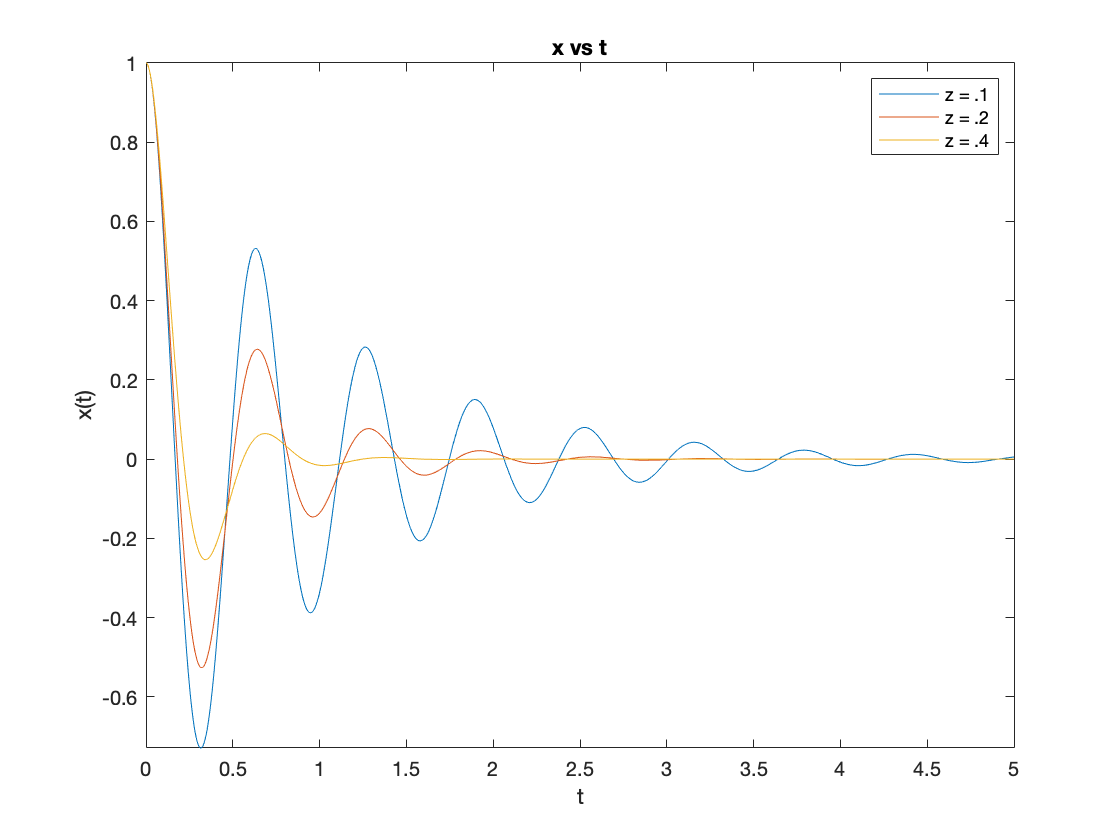

fplot(x3,[0 5])
legend('z = .1', 'z = .2', 'z = .4');
hold off


figure  %new figure
x4 = subs(x,[x0 z w],[1 .1 10])     %d plotting for different w values

$$x4 = -\frac{5\,\sqrt{99}\,{\mathrm{e}}^{t\,\left(-1+\sqrt{99}\,\mathrm{i}\right)}\,\left(\frac{1}{10}+\frac{\sqrt{99}\,\mathrm{i}}{10}\right)\,\mathrm{i}}{99}-\frac{5\,\sqrt{99}\,{\mathrm{e}}^{-t\,\left(1+\sqrt{99}\,\mathrm{i}\right)}\,\left(-\frac{1}{10}+\frac{\sqrt{99}\,\mathrm{i}}{10}\right)\,\mathrm{i}}{99}$$

fplot(x4,[0 5])
hold on
title('x vs t');
xlabel('t');
ylabel('x(t)');
x5 = subs(x,[x0 z w],[1 .1 20])

$$x5 = -\frac{5\,\sqrt{99}\,{\mathrm{e}}^{t\,\left(-2+2\,\sqrt{99}\,\mathrm{i}\right)}\,\left(\frac{1}{10}+\frac{\sqrt{99}\,\mathrm{i}}{10}\right)\,\mathrm{i}}{99}-\frac{5\,\sqrt{99}\,{\mathrm{e}}^{-t\,\left(2+2\,\sqrt{99}\,\mathrm{i}\right)}\,\left(-\frac{1}{10}+\frac{\sqrt{99}\,\mathrm{i}}{10}\right)\,\mathrm{i}}{99}$$

fplot(x5,[0 5])
x6 = subs(x,[x0 z w],[1 .1 40])

$$x6 = -\frac{5\,\sqrt{99}\,{\mathrm{e}}^{t\,\left(-4+4\,\sqrt{99}\,\mathrm{i}\right)}\,\left(\frac{1}{10}+\frac{\sqrt{99}\,\mathrm{i}}{10}\right)\,\mathrm{i}}{99}-\frac{5\,\sqrt{99}\,{\mathrm{e}}^{-t\,\left(4+4\,\sqrt{99}\,\mathrm{i}\right)}\,\left(-\frac{1}{10}+\frac{\sqrt{99}\,\mathrm{i}}{10}\right)\,\mathrm{i}}{99}$$

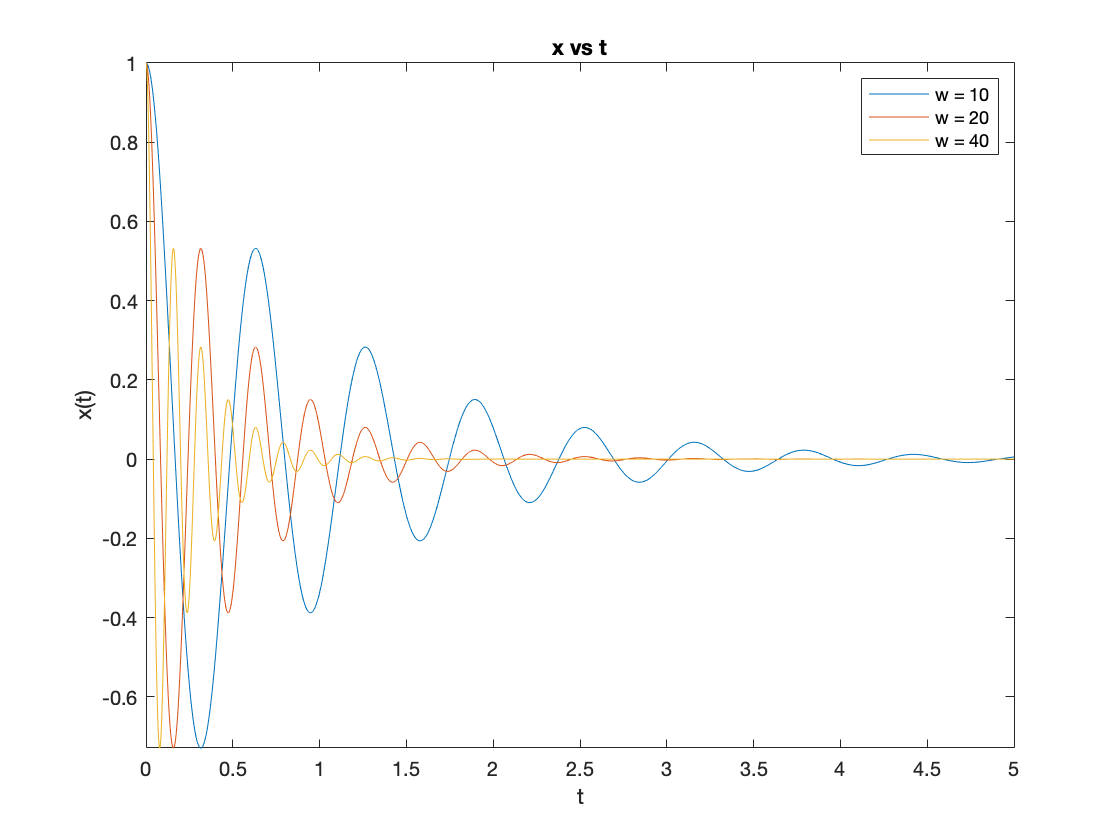

fplot(x6,[0 5])
legend('w = 10', 'w = 20', 'w = 40');
hold off